# Señal continua y señales discretas

Señal continua x(t)

Señal discreta x[t]

Uso de latex en los live scripts:


$$$R_{\mu\nu} - \frac{1}{2}g_{\mu\nu} = 8\pi T_{\mu\nu}$$$


syms t      % Declaramos variable simbólica.
y = cos(t)  % Declaramos función simbólica.

$$y = \cos\left(t\right)$$

% Function Handle
y_fh = @(t) cos(t) %--> creamos una function handle a partir de una variable simbólica.

y_fh = function_handle with value:
    @(t)cos(t)



% Las function handle son más rápidas en su evaluación pero 
% no se puede hacer algebra.

y2 = y + sin(t) + exp(-t) % Algebra con una función simbólica.

$$y2 = {\mathrm{e}}^{-t}+\cos\left(t\right)+\sin\left(t\right)$$


y_fh([1,2,3]) % Evaluación de una funtion handle

ans =     0.5403   -0.4161   -0.9900


subs(y,t,[1,2,3]) % Evaluación de una función simbólica.

$$ans = \left(\begin{array}{ccc} \cos\left(1\right) & \cos\left(2\right) & \cos\left(3\right) \end{array}\right)$$

% Pasamos de una función simbólica a ua function handle

y2_fh = matlabFunction(y2)

y2_fh = function_handle with value:
    @(t)exp(-t)+cos(t)+sin(t)


y2_fh([1 2 3])

ans =     1.7497    0.6285   -0.7991


%% Funciones discretas y continuas

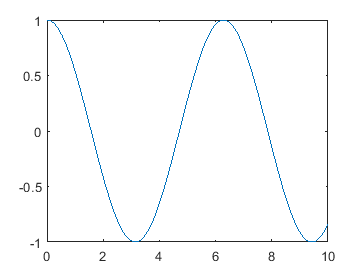

% Ploteo función simbólica
figure
fplot(y,[0,10])

% Ploteo function handle
figure
fplot(y_fh,[0,10])

% Ploteo de manera discreta --> steam
tiempos = 0:10

tiempos =      0     1     2     3     4     5     6     7     8     9    10


valores = y_fh(tiempos)

valores =     1.0000    0.5403   -0.4161   -0.9900   -0.6536    0.2837    0.9602    0.7539   -0.1455   -0.9111   -0.8391


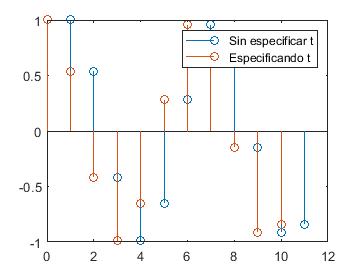


figure
stem(valores)
hold on  % --> Para poder graficar sobre una misma figura.
stem(tiempos,valores)
hold off
legend("Sin especificar t","Especificando t")

% Graficando con mayor resolución

tiempos = 0:0.1:10

tiempos =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


valores = y_fh(tiempos)

valores =     1.0000    0.9950    0.9801    0.9553    0.9211    0.8776    0.8253    0.7648    0.6967    0.6216    0.5403    0.4536    0.3624    0.2675    0.1700    0.0707   -0.0292   -0.1288   -0.2272   -0.3233   -0.4161   -0.5048   -0.5885   -0.6663   -0.7374   -0.8011   -0.8569   -0.9041   -0.9422   -0.9710   -0.9900   -0.9991   -0.9983   -0.9875   -0.9668   -0.9365   -0.8968   -0.8481   -0.7910   -0.7259   -0.6536   -0.5748   -0.4903   -0.4008   -0.3073   -0.2108   -0.1122   -0.0124    0.0875    0.1865


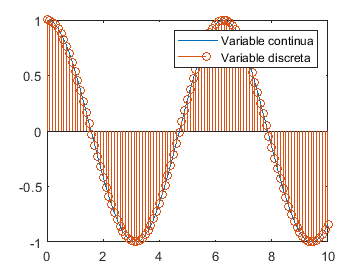


figure
fplot(y_fh,[0 10])    % --> Ploteo variable continua.
hold on
stem(tiempos,valores) % --> Ploteo variable discreta.
hold off
legend("Variable continua","Variable discreta")

**Ejercicio** 1

f1 = 3*exp(0.4*t)

f1 = 	1.0e+17 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


f2 = 2*exp(-0.9*t)

f2 =     2.0000    1.9821    1.9643    1.9467    1.9293    1.9120    1.8949    1.8779    1.8611    1.8444    1.8279    1.8115    1.7953    1.7792    1.7632    1.7474    1.7318    1.7163    1.7009    1.6856    1.6705    1.6556    1.6407    1.6260    1.6115    1.5970    1.5827    1.5685    1.5545    1.5406    1.5268    1.5131    1.4995    1.4861    1.4728    1.4596    1.4465    1.4335    1.4207    1.4080    1.3954    1.3829    1.3705    1.3582    1.3460    1.3340    1.3220    1.3102    1.2984    1.2868


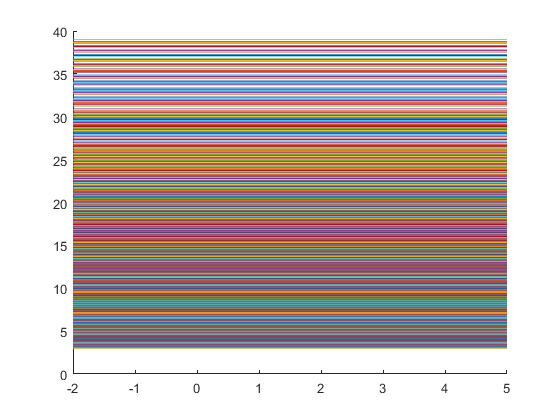

Error using symvar>isquoted (line 154)
Quotes in S are not in pairs.

Error in symvar (line 49)
q = isquoted(s);

Error in texlabel>greeks (


figure
fplot(f1,[-2 5])

hold on
fplot(f2,[-2 5],"LineStyle","--")
hold off
legend("f1(t)","f2(t)")

**Ejecicio 2 **

f1 = cos(t) + sin(3*t)
figure
fplot(f1,[0 6*pi],"Color","black","LineWidth",1.5)

**Ejercicio 3**

t0 = 0 ;
tf = 1 ;

theta = 5  ;
w     = 50 ;

c = 1  ;
r = -3 ;

figure
f1 = c*exp(r*t)*cos(w*t+theta);
fplot(f1,[t0 tf])

### Clase: Gráfica cos + sin

t=0:0.01:100;
x=sin(t)+cos(t);
figure
plot(t,x)
